# Sea Water Reverse Osmosis

This livescript covers how to use some of the advanced features of this toolbox in sea water reverse osmosis (SWRO) modeling. The features covered are polarization, variable membrane transport parameters, and scaling/fouling.

## Basic Model

First we will look at a basic model that does not include any of these advanced features to see the base line model results.

open('SWRO.slx')
set_params_700psi;
set_param('SWRO/Membrane','coefficient_type','1') % Constant
set_param('SWRO/Membrane','A_w','0.104')
set_param('SWRO/Membrane','A_w_unit','l/(m^2*hr*psi)')
set_param('SWRO/Membrane','B_s','0.108')
set_param('SWRO/Membrane','B_s_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','polarization_type','1') % None
out = sim('SWRO');
basic_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
basic_900 = out.simlog;
set_params_500psi
out = sim('SWRO');
basic_500 = out.simlog;

cases = {basic_500, basic_700, basic_900};
results = calc_ro_metrics(cases,60);
results.Applied_Pressure = [500; 700; 900];
BasicResultsTable = ResultsTable(results);
disp(BasicResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.2               3.5            3.9               99.6                        310                    35.4  
             700                      20              20.7           12.8               99.9                        167                   206.2  
             900                    32.1              39.8           15.3               99.9                        102                   397.2  



We ran the basic desalination model at 3 different pressures for 9 minutes after ramping up over 60 seconds. We can see some expected behaviors. As applied pressure increases, feed flow, flux, recovery ratio, and salt rejection all increase while permeate concentration decreases. We also see net driving pressure (NDP) increase. NDP is the difference between the hydraulic pressure difference and the osmotic pressure difference accross the membreane. However, we can do better. One way we can improve upon this model is through adding polarization.

## Polarization

Polarization is the effect where the fluid near the membrane has a higher concentration than the bulk flow, increasing the osmotic pressure difference and therefore reducing the NDP, flux, etc. This occus because as water flows through the membrane, it leaves the salt it was carrying right at the membrene surface which must then diffuse back into the bulk. We have included two ways of modeling polarization in the membrane block. The first and "more proper" way is to actually model this through diffusion. 

### Diffusion

In static flow, our diffusion equation for mass flow of solute $x$ ($\dot{M_x }$) is


$$$\dot{M}_x = D_x\frac{\Delta c}{\ell}A$$$


where $D_x$ is the diffusivity of our mixture, $\Delta c$ is the concentration difference, $\ell$ is the length scale that concentration difference is streatched over, and $A$ is the cross sectional area. Diffusion is actually present in the connections between many Simscape fluids blocks, however, the impact if quite small and so tuning $A$ and $\ell$ seperately is not important. In this domain, diffusion can be really important, therefore everyblock with volume has the option to set custom port lengths, which should be set to $\frac{\ell}{2}$ on both sides of the connection. Let's load an example.

open('diffusion_example.slx')

This example roughly represents a 2 liter bottle where initially, the bottom half of the bottle is full of a high concentration salt water and the top half has pure freshwater. Let's see what happens when we run the simulation for 250 days.

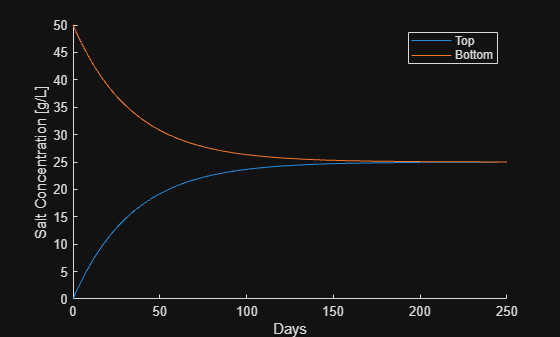

out = sim('diffusion_example');
t_diff = out.simlog.Bottom.x_I.series.time();
x_btm = out.simlog.Bottom.x_I.series.values('g/l');
x_top = out.simlog.Top.x_I.series.values('g/l');
figure('name','Diffusion Example')
line(t_diff/(60*60*24),x_top,'DisplayName','Top')
line(t_diff/(60*60*24),x_btm,'DisplayName','Bottom')
xlabel('Days')
ylabel('Salt Concentration [g/L]')
legend('Location','Best')

It's very important to note the time scale for this, 250 days. It is highly likely the 2-liter will be disturbed in some way, shaken, moved, etc. and will therfore mix much faster. As we can see, bulk motion of flow is going to dominate most mass transfer, unless we have very small volumes and very small diffusion length scales. In membrane polarization, we do.

In our membrane, we can model this diffusion polarization by creating a very small volume chamber that interacts with the membrane instead of the bulk volume. Let's add this to our basic SWRO model

### Diffusion in SWRO

open('SWRO.slx')
set_param('SWRO/Membrane','polarization_type','2') % Discrete Boundary Layer Volume
set_param('SWRO/Membrane','boundary_height','0.07')
set_param('SWRO/Membrane','boundary_height_unit','mm')
set_params_500psi;
out = sim('SWRO');
boundary_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
boundary_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
boundary_900 = out.simlog;
cases = {boundary_500, boundary_700, boundary_900};

results = calc_ro_metrics(cases,60);

Applied_Pressure = [500; 700; 900];

BoundaryResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(BoundaryResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.1               2.8            3.1               99.5                        320                    28.3  
             700                    19.4              15.6            9.9               99.9                        215                   155.4  
             900                    30.7                29           11.6               99.9                        157                   289.3  



As we can see, this reduced the performance as predicted. The challenge with this strategy is setting that "boundary layer height" parameter. Unfortunately this is not a very practical parameter to use. Hard to measure and not reported in any membrane spec sheets. A more practical (but less "proper") way of quantifying polarization is through an exponential modifier on the concentration. 

### Exponential Modifier

The exponential modifier adjusts the concentration measurment ($$c_m$$) in a pipe based on the flow velocity and mass transfer of both solute and solvent. 


$$c_m = c \exp \left( \frac{J_{eff}}{k}\right)$$


where $c$ is the bulk concentration in the pipe, $J_{eff}$ is the effective solvent flux (more on this to come, for now just understand it as solvent flux), and $k$ is calculated as:


$$$$k = \frac{ShD_{x}}{d_h}$$$$


where $Sh$ is the Sherwood number, $D_{x}$ is the diffusivity of the solute (a fluid property), and $d_h$ is the hydraulic diameter of the feed side channel. The Sherwood number can be calculated through the following:


$$Sh = 0.14Re^{0.64}Sc^{0.42}$$



$$Re = \frac{vd_{h}}{\nu}$$



$$Sc = \frac{\nu}{D_{NaCl}}$$


where $v$ is the flow velocity and $\nu$ is the kinematic viscosity which we have access to through fluid properties.

Let's see how this compares.

open('SWRO.slx')
set_param('SWRO/Membrane','polarization_type','3') % Exponential Modifier
set_params_500psi;
out = sim('SWRO');
expmod_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
expmod_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
expmod_900 = out.simlog;
cases = {expmod_500,expmod_700,expmod_900};
results = calc_ro_metrics(cases,60);
Applied_Pressure = [500; 700; 900];

ExpModResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(ExpModResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                      11               1.8             2                99.8                        335                    17.8  
             700                    18.8              10.7             7                99.9                        277                   106.7  
             900                    29.9                22           9.1                99.9                        211                   219.7  



Once again this demonstrates a similar trend, but is easier to work with than the discete boundary volume strategy.

## Variable Transport Parameters

Water and salt permeability in SWRO membranes are not constant under all flow conditions, different NDPs can lead to different permeabilities. While constant permeabilities are perfectly fine in situations where the membrane is always operated under constant conditions, variable feed pressures/compositions and simulating under different operating conditions require variable transport parameters.

For ease of use our membrane block has the option to use a look-up table instead of these constant parameters, indexed by NDP.

open('SWRO.slx')
set_param('SWRO/Membrane','coefficient_type','2') % Variable - Look-up table
set_param('SWRO/Membrane','A_table','[0.121,0.109,0.104,0.100,0.099]')
set_param('SWRO/Membrane','A_table_unit','l/(m^2*hr*psi)')
set_param('SWRO/Membrane','B_table','[0.090,0.102,0.108,0.116,0.119]')
set_param('SWRO/Membrane','B_table_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','NDP_index','[39.2,107.3,182.7,259.3,332.7]')
set_param('SWRO/Membrane','NDP_index_unit','psi')
set_params_500psi;
out = sim('SWRO');
vtp_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
vtp_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
vtp_900 = out.simlog;
cases = {vtp_500,vtp_700,vtp_900};
results = calc_ro_metrics(cases,60);
Applied_Pressure = [500; 700; 900];

VTPResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(VTPResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                      11               1.8           2.1                99.8                        279                    15.8  
             700                    18.8              10.9           7.2                99.9                        255                   103.1  
             900                    29.8              21.8             9                99.9                        217                   222.2  



What we notice is that while this doen't impact the flux all that much, it has a pretty significant impact on the permeate concentration. So in applications where peremeate concentration is important, this could be an imporant feature to leverage (and it doesn't slow the simulation down at all).

## Scaling/Fouling

Of all the advnaced features presented in this livescript, none are as important as scaling/fouling. This has a major impact on performance and modeling how quickly these phemomena occur can help engineers design systems to reduce the regularity of costly cleaning events. While a truly meaningful SWRO implementation won't be available until the multiple solutes work is complete, we can still showcase the functionality. 

## Helper Functions

function set_params_500psi()
    set_param('SWRO/PS Constant','constant','500')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','500/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.8579e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_700psi()
    set_param('SWRO/PS Constant','constant','700')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','700/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.6025e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_900psi()
    set_param('SWRO/PS Constant','constant','900')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','900/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.3242e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function time_avg = time_avg_after_t0(time,series,t0)
    idx = time>=t0;
    t = time(idx);
    y = series(idx);
    time_avg = trapz(t,y) / (t(end) - t(1));
end

function results = calc_ro_metrics(cases,t0)

nCases = numel(cases);

results.Feed_Flow      = zeros(nCases,1);
results.Flux           = zeros(nCases,1);
results.Recovery       = zeros(nCases,1);
results.Salt_Rejection = zeros(nCases,1);
results.Perm_Conc      = zeros(nCases,1);

t = cell(nCases,1);

for i = 1:nCases
    c = cases{i};

    t{i} = c.Feed.mdot_A.series.time;

    results.Feed_Flow(i) = time_avg_after_t0( ...
        t{i}, ...
        -c.Feed.mdot_A.series.values('kg/min') ./ c.Feed.rho_I.series.values('kg/l'), ...
        t0);

    results.Flux(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Permeate.mdot_A.series.values('kg/hr') ./ c.Feed.rho_I.series.values('kg/l') ./ 7.4, ...
        t0);

    results.Recovery(i) = time_avg_after_t0( ...
        t{i}, ...
        -c.Permeate.mdot_A.series.values('kg/hr') ./ c.Feed.mdot_A.series.values('kg/hr'), ...
        t0);

    results.Salt_Rejection(i) = time_avg_after_t0( ...
        t{i}, ...
        -c.Brine.mdot_A_x.series.values('kg/hr') ./ c.Feed.mdot_A_x.series.values('kg/hr'), ...
        t0);

    results.Perm_Conc(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Membrane.P.x.series.values('mg/l'), ...
        t0);
end

results.NDP = zeros(10,nCases);

for ii = 1:10
    for jj = 1:nCases
        results.NDP(ii,jj) = time_avg_after_t0( ...
            t{jj}, ...
            cases{jj}.Membrane.unit(ii).membrane_eqs.NDP.series.values('psi'), ...
            t0);
    end
end

results.Mean_NDP = mean(results.NDP,1).';

end

function ResultsTable = ResultsTable(results)
    ResultsTable = table( ...
        results.Applied_Pressure, ...
        round(results.Feed_Flow(:),1), ...
        round(results.Flux(:),1), ...
        round(results.Recovery(:)*100,1), ...
        round(results.Salt_Rejection(:)*100,1), ...
        round(results.Perm_Conc(:),0), ...
        round(results.Mean_NDP,1), ...
        'VariableNames', { ...
            'Applied Pressure [psi]', ...
            'Feed Flow [L/min]', ...
            'Flux [LMH]', ...
            'Recovery [%]', ...
            'Salt Rejection [%]', ...
            'Permeate Concentration [mg/L]', ...
            'NDP [psi]' ...
        });
end
